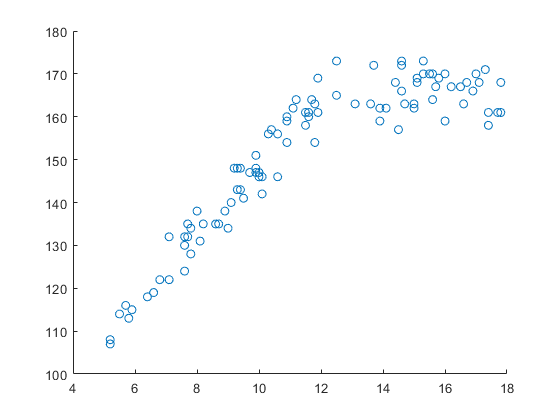

data=readtable("height_of_girls.txt");
X=table2array(data(:,"Age"));
Y=table2array(data(:,"Height"));
scatter(X,Y)

f1 =@(x) (x<12).*(x-12);
f2 =@(x) ones(size(x));
A = [f1(X),f2(X)];
c=A\Y;
g = @(x) c(1).*f1(x)+c(2).*f2(x)

g = function_handle with value:
    @(x)c(1).*f1(x)+c(2).*f2(x)


XX = linspace(min(X),max(X),100)

XX =    5.200000000000000   5.327272727272727   5.454545454545455   5.581818181818182   5.709090909090909   5.836363636363637   5.963636363636364   6.090909090909092   6.218181818181819   6.345454545454546   6.472727272727273   6.600000000000001   6.727272727272728   6.854545454545455   6.981818181818182   7.109090909090909   7.236363636363636   7.363636363636364   7.490909090909091   7.618181818181819   7.745454545454546   7.872727272727273   8.000000000000000   8.127272727272727   8.254545454545454   8.381818181818183   8.509090909090910   8.636363636363637   8.763636363636365   8.890909090909091   9.018181818181819   9.145454545454546   9.272727272727273   9.400000000000002   9.527272727272727   9.654545454545456   9.781818181818181   9.909090909090910  10.036363636363637  10.163636363636364  10.290909090909093  10.418181818181818  10.545454545454547  10.672727272727274  10.800000000000001  10.927272727272729  11.054545454545455  11.181818181818183  11.309090909090909  11.4363636363

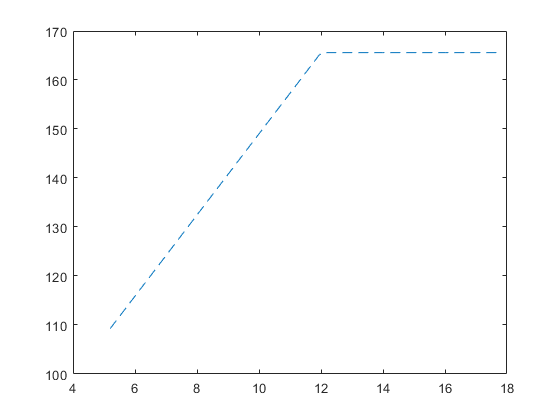

plot(XX,g(XX),"--")

g(12)

ans =      1.655819756316577e+02


g(5)

ans =      1.076141052748347e+02
